# **Примерчики MatLab**

## Преобразование Фурье

Переводим в спектр, отсекаем минимальыне частоты -> фильтрация шумов. (см. гугл)

## Линейная Регрессия

(см. гугл)

## Polyfit

Приближаем полиномчиками (полиномиальная регрессия)

p = [1 2 1];
x = 0:0.1:3;
size = length(x);
y = polyval(p,x) + rand(1,size);
plot(x, y, 'o');
p_fit = polyfit(x,y,2)

p_fit =     1.0563    1.8833    1.5097


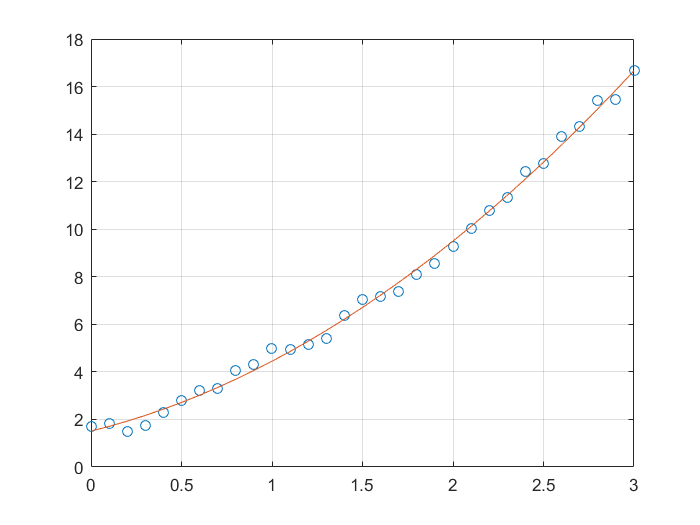

yp = polyval(p_fit, x);
hold on;
grid on;
plot(x, yp)

Несколько графиков в одном

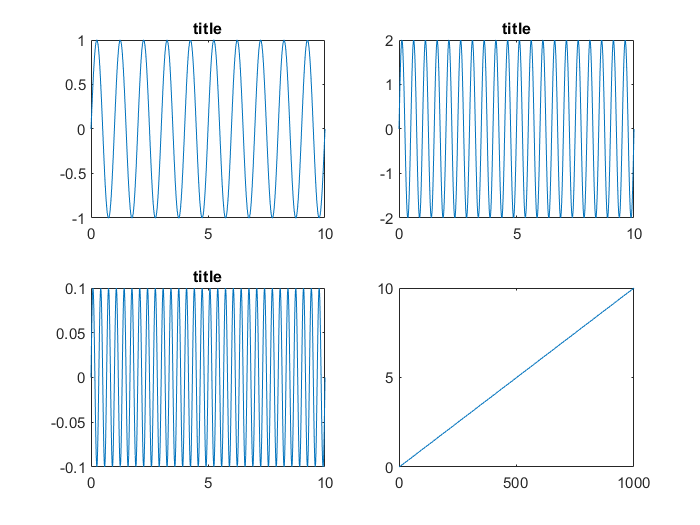

x = 0:0.01:10;
sines = [sin(2*pi*x); 2*sin(2*2*pi*x); 0.1*sin(3*2*pi*x); sin(2*pi*x + pi/4)];
figure(1);
for i=1:4
    subplot(2,2,i);
    plot(x, sines(i,:));
    title("title");
end
figure(2)
plot(x)

Загрузка текстовых данных

load("test.txt");

Error using load
Unable to read file 'test.txt'. No such file or directory.

%data = load("test.txt")%
save('out.csv', 'data', '-ascii');

Работа со строками

x = "abc"
y = strcat(x, "def")
x_arr = ['a', 'b', 'c']
y_arr = ['d', 'e', 'f']
cat = [x_arr, y_arr]
x_chat = 'abc'

Операции с матрицами

t = linspace(1,10,100)

t =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


A = diag([1,2])

A =      1     0
     0     2


B = diag(4:6)

B =      4     0     0
     0     5     0
     0     0     6


Big = blkdiag(A,B)

Big =      1     0     0     0     0
     0     2     0     0     0
     0     0     4     0     0
     0     0     0     5     0
     0     0     0     0     6


AAA = repmat(A,1,3)

AAA =      1     0     1     0     1     0
     0     2     0     2     0     2


d = det(A)

d = 2

lambda = eig(A)

lambda =      1
     2


[lambda, v] = eig(A)

lambda =      1     0
     0     1


v =      1     0
     0     2


left = lambda(2)*(v(:,2))

left =      0
     0


right = A*v(:,2)

right =      0
     4


A_poly = poly(A)

A_poly =      1    -3     2


Операции с полиномами

A = diag([1,2])

A =      1     0
     0     2


A_poly = poly(A)

A_poly =      1    -3     2


x = polyval(A_poly, 1)

x = 0

r = roots(A_poly)

r =      2
     1


p = poly(r)

p =      1    -3     2


r1 = [j,j]; %комплексные единицы%
poly(r1)

ans =    1.0000 + 0.0000i   0.0000 - 2.0000i  -1.0000 + 0.0000i


p2 = [1 2 3 4]

p2 =      1     2     3     4


p_x_p2 = conv(p,p2)

p_x_p2 =      1    -1    -1    -1    -6     8


% deconv - деление %
p2_der = polyder(p2)

p2_der =      3     4     3


Лямбда-выражения

f = @(x, y)( x + y);
z = f(1,2)